# P02: Señales discretas

Integrantes:

- Edgar Vargas Rodríguez

- Jaqueline Tinoco Vázquez

- Mauricio Paulo Peña Sánchez

## **Objetivo**

- Conocer métodos básicos de integración numérica

- Manipulación de instrucciones en MATLAB

- Simular convoluciones y correlaciones de señales continuas

- Simular convoluciones y correlaciones de señales discretas

## Introducción

## Desarrollo

### Problema 1

Para el PR04 reporte la grafica de la simulación númerica de la convolución y compare con el resultado análitico que obtuvo para el problema 1, esto es, su práctica tendrá que incluir una llamada a la funciónn *convconm* y posteriormente se tendrá que mostrar (mediante el Publish) la gráfica tanto de las señales involucradas como el resultado de la convolución, y en esta última gráficara su resultado analitico, se tendrá que incluir el resultado analitico.

- Realiza la convolución de las siguientes señales

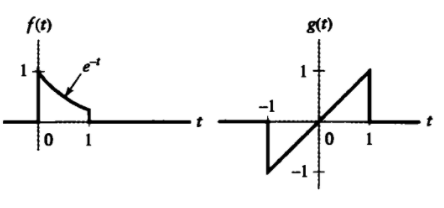


$$f(t)= \begin{cases}
e^{-t} &0\le t<1\\
0 &\text{otro caso} \\
\end{cases}$$



$$g(t)= \begin{cases}
t &-1\le t\le 1\\
0 &\text{otro caso} \\
\end{cases}$$


la convolucion la definimos como h(t)


$$h(t) = \begin{cases}
0 &t<-1\\
\frac{2}{e^{t+1}}+t-1 &-1\le t<0\\
\frac{2-t}{e}+t-1 &0\le t<1\\
\frac{2-t}{e} &1\le t<2\\
0 &2<t\\
\end{cases}
$$


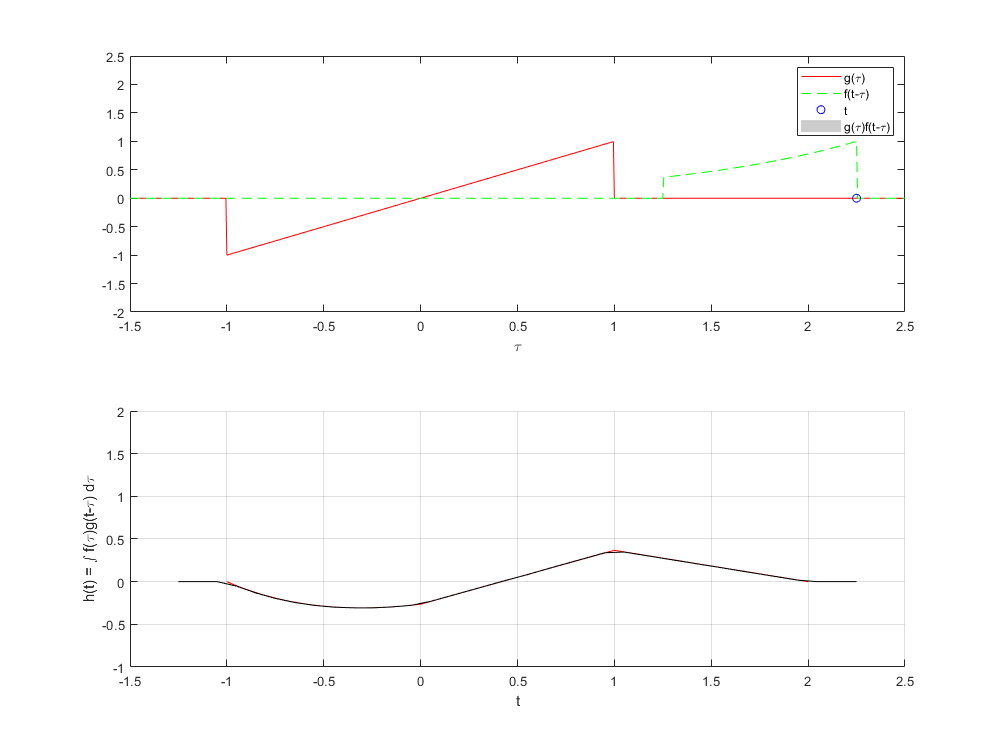

f = @(t) exp(-t).*(t>=0 & t<1);
g = @(t) t.*(t>=-1&t<1);
convconm(f,g)

A continuacion mostramos una animación de como la grafica de la correlación calculada en el PR04, pasa por los mismos puntos que en la simulación de MATLAB.

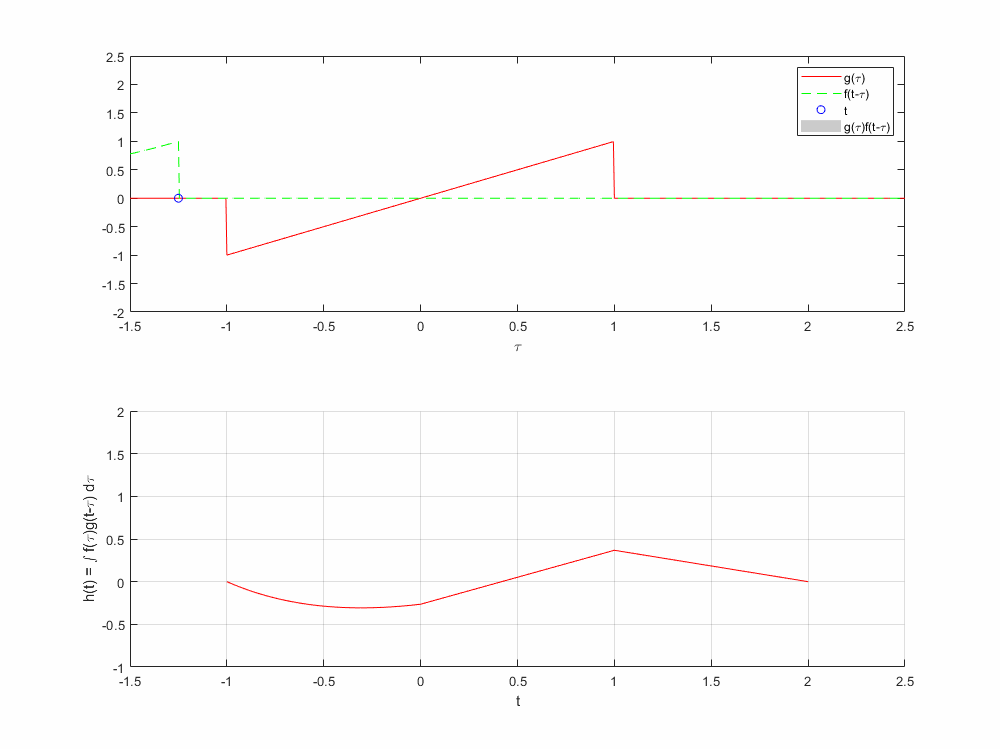

### Problema 3

Realice la simuación de la convolución de las señales (c) con (d) del problema 3.1.1

**3.1-1** Find the energy of the signals depicted in Fig. P3.1-1.

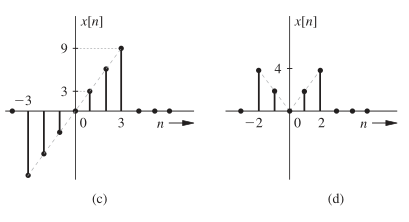

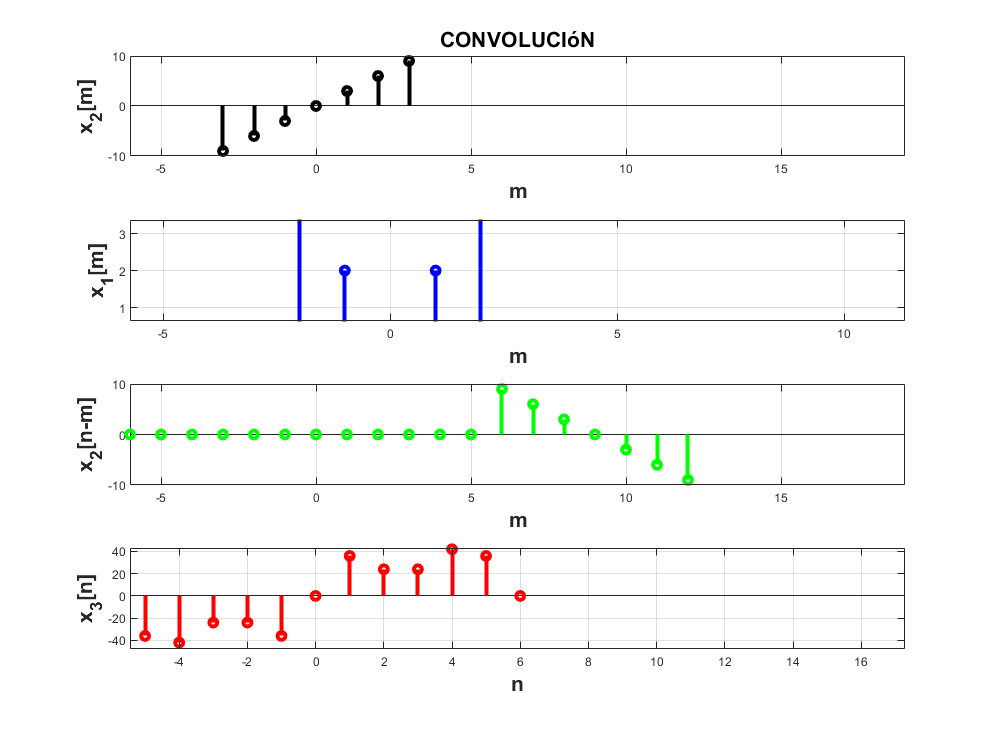

n=-3:3;
b=[  -9 -6 -3 0 3 6 9  ];
a=[  0  4  2 0 2 4 0  ];
convdisc([n;a],[n;b])

Simulación de la convolución discreta.

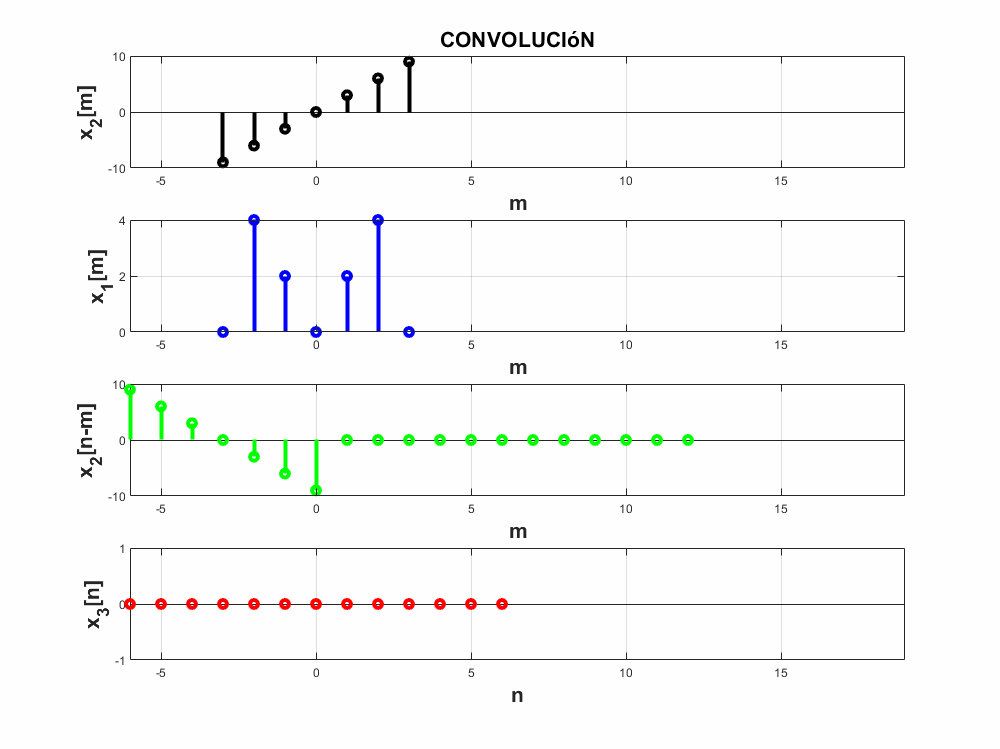

### Problema 4

### Problema 5

## Referencias

Lathi, E. B. P., & Green, A. P. R. (2017). Linear Systems and Signals (3rd ed.). Oxford University Press, USA.